%lab 3 part A
clear all
clc

## setting up inputs

x1 = [ -1 -1 1 1 ]; x2 = [ -1 1 -1 1 ]; tk = [ -1 1 1 -1 ];

theta = 0.001;
eta = 0.1;
epoch = 0; cond=1; features=2;
w_ji = rand(2,3);
wk_j = rand(1,3);

mean_x1 = mean(x1);
std_x1 = std(x1);
Norm_x1 = (x1 - mean_x1)/std_x1;
mean_x2 = mean(x2);
std_x2 = std(x2);
Norm_x2 = (x2 - mean_x2)/std_x2;
X1 = Norm_x1;
X2 = Norm_x2;

## feed forward and backprobagation

while (cond==1)
    
    epoch = epoch + 1; 
    m = 0;
    %initializing the delta values
    delta_w_ji = zeros(2,3); delta_wkj = zeros(1,3);
    
    for m = 1:length(X1)
          xinput = [ 1 X1(m) X2(m) ]; 
          
       netj = zeros(1,2);
       yj = zeros(1,2);
       
        for j = 1:features
           netj(j) = w_ji(j,:) * xinput';
           yj(j) = tanh(netj(j)); 
           y_deriv = sech(netj(j));
        end
        yj = [ 1 yj ];
        
        net_k = wk_j * yj';
     
        zk(m) = tanh(net_k);
        z_deriv = sech(net_k);
        delta_k = (tk(m) - zk(m)) * z_deriv;

        delta_j = zeros(1,2);
        for j = 1:features
            delta_j(j) = (1 - (tanh(netj(j))).^2) * delta_k * wk_j(j+1);
        end
        
        for i = 1:3
            for j = 1:features
                delta_w_ji(j,i) =  delta_w_ji(j,i) + eta * delta_j(j) * xinput(i)';
            end
        end
    
        
        for l = 1:3
            delta_wkj(l) =   delta_wkj(l) + eta * delta_k * yj(l)';
        end
        
    end

  
     w_ji = w_ji + delta_w_ji ;
     wk_j = wk_j + delta_wkj;
    
    
    Jp(epoch) = 0.5 * (((tk' - zk')') * (tk' - zk')); 
    
    if (epoch == 1)
        JP_total = Jp(epoch);
    else
        JP_total = Jp(epoch-1) - Jp(epoch);
    end
    
    JP_total = abs(JP_total);
    if JP_total<theta
       cond=0;
        break
    end
    
    
end

y_intersect1 = -w_ji(1,1)/w_ji(1,3); slope1 = -w_ji(1,2)/w_ji(1,3);
x_axis = -4:0.01:4;
boundary1 = slope1 * x_axis + y_intersect1;

y_intecect2 = -w_ji(2,1)/w_ji(2,3);
sope2 = -w_ji(2,2)/w_ji(2,3);
boundary2 = y_intecect2 + sope2*x_axis;

y_intersept_k = -wk_j(1)/wk_j(3);
slope_k = -wk_j(2)/wk_j(3);
boundary_y = slope_k * x_axis + y_intersept_k;

% plotting the result
figure(1);

plot(x1(:,1:2),x2(:,1:2),'mo');
hold;

Current plot held


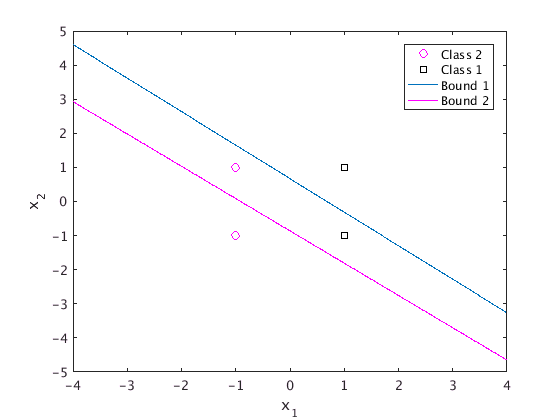

plot(x1(:,3:4),x2(:,3:4),'ks');
plot(x_axis, boundary1);
plot(x_axis, boundary2, 'm');
xlabel('x_1');
ylabel('x_2');
legend('Class 2', 'Class 1','Bound 1', 'Bound 2');

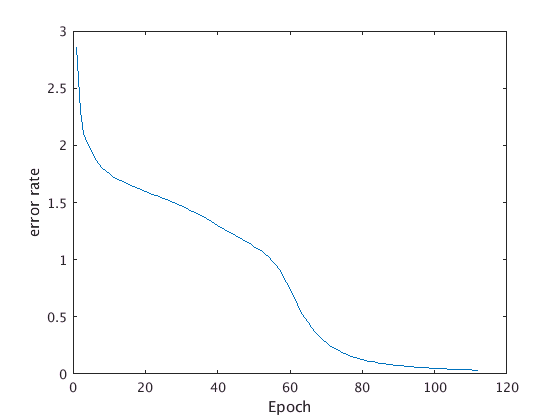




% learning curve
figure(2)
plot(Jp)
xlabel('Epoch'); ylabel('error rate');

## calculating the accuracy

Accuracy = 0;
correctly_classified = 0;
for i=1:length(X1)
    if ( (zk(i)<0 && tk(i)==-1) || (zk(i)>0 && tk(i) == 1) );
        correctly_classified = correctly_classified + 1;
    end
end
                        
Accuracy= correctly_classified/length(X1)*100

Accuracy = 100

epoch

epoch = 112